clear
sensor_pin = 'A5';
pan_pin = 'D9';
tilt_pin = 'D10';



% a = arduino();
a = arduino('COM10', 'Uno', 'Libraries', 'Servo');

pan_servo = servo(a,pan_pin,"MinPulseDuration",700*10^-6,'MaxPulseDuration',2300*10^-6);
tilt_servo = servo(a,tilt_pin,"MinPulseDuration",700*10^-6,'MaxPulseDuration',2300*10^-6);

%move servo to middle position for next scan

writePosition(pan_servo,Deg2Pos(0));
writePosition(tilt_servo,Deg2Pos(0));

% initilize pan and tilt servo to upper left corner of scan image
count = 1;
points = [];
for tilt_angle = -15:2:50
    disp(tilt_angle);
    writePosition(tilt_servo,Deg2Pos(tilt_angle));
    pause(0.1);
    for pan_angle = -30:2:30
        disp(pan_angle);
        writePosition(pan_servo,Deg2Pos(pan_angle));
        %take a scan here for each step
        points= [points,get_coordinates(a,pan_angle,tilt_angle)];
        count = count + 1;
        pause(0.1);
    end

end

   -15



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



   -13



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



   -11



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    -9



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    -7



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    -5



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    -3



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    -1



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



     1



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



     3



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



     5



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



     7



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



     9



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    11



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    13



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    15



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    17



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    19



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    21



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    23



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    25



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    27



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    29



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    31



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    33



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    35



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    37



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    39



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    41



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    43



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    45



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    47



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    49



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



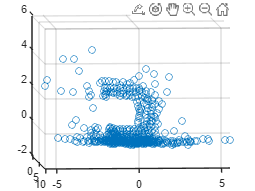

%% DO NOT TOUCH

clf
x = points(1,:);
x = x(z<10);
y = points(2,:);
y = y(z<10);
z = points(3,:);
z = z(z<10);
scatter3(x,z,y)

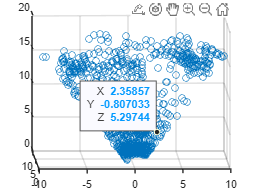

clf
x = points(1,:);
y = points(2,:);
z = points(3,:);
scatter3(x,y,z)

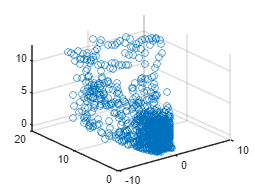

%% TOUCH
clf
z = points(3,:);
%z = z(z<15);
x = points(1,:);
%x = x(z<15);
y = points(2,:);
%y = y(z<15);
scatter3(x,z,y)

disp(points);



function pos = Deg2Pos(degree)
% degree ranges from -90 to 90
pos = 0.5+degree/180;
end

function distance = get_distance(voltage)
distance = 18.9*exp(-0.7578*voltage);
end 
